# **Thermocouple Emulation**

This example shows you how to setup the IO975-16 I/O module, in order to verify the basic functionality.

The IO975 I/O module is a low voltage analog output module and an ideal solution for simulating most thermocouple types and performing ECU testing. Each channel supports accurate output voltages up to +/-100 mV and resolutions down to 0.7 μV, to best meet your applications.

The Simulink model features the [IO975 - Thermocouple Simulation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io974_io975_thermocouple_simulation) block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO975-16 I/O module installed

- Connector cable from the I/O module to the terminal board

- 78-pin terminal board

- Oscilloscope or multimeter

### Test Setup

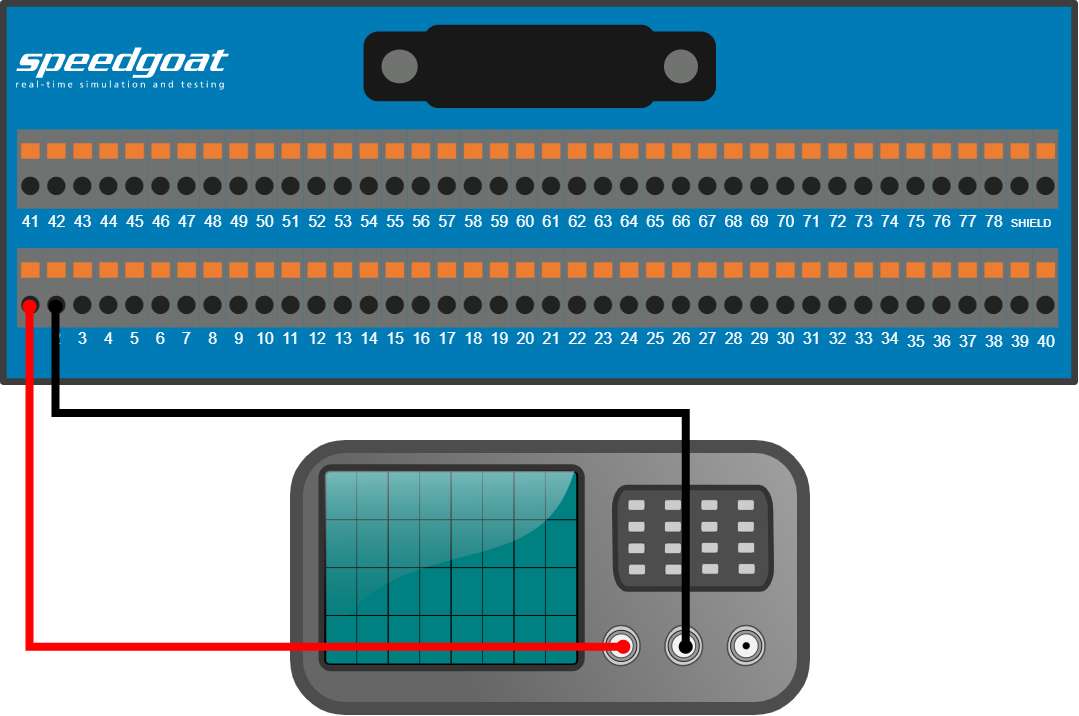

On the terminal board of the IO975 I/O module, connect an oscilloscope to one of the two enabled channels to measure the voltage as shown above. [IO975 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io974_io975_pin_mapping)

## Initialize and Open the Simulink model

 
% Load temperature table for thermocouples
load('sldemo_tc_blocks_data.mat');

% Open Simulink model
modelName = 'sgMdl_ThermocoupleEmulation';
open_system(modelName);

### Model Description

In the model, two thermocouple elements are simulated. On channel one a type J thermocouple is used, and the input temperature is a triangle wave signal that is connected to a lookup table that converts the applied temperature to a voltage for this specific thermocouple type. Further gain block is used to convert the voltage to millivolts as this is the expected unit on the input ports. A saturation block is used to keep the signal in the range of +/-100 mV. For this channel the auto range is selected, which provides the best accuracy on all voltage levels.

On channel three, the temperature source is a sinusoidal signal. The lookup table for this thermocouple element is configured to simulate a type K element. Same as for channel one, the signal is then converted to millivolts and limited to +/-20 mV, as this is the selected voltage range for this channel.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the applied voltage is correctly output, check the signals on the connected oscilloscope. The two output channels must display the converted temperature signals in millivolts.

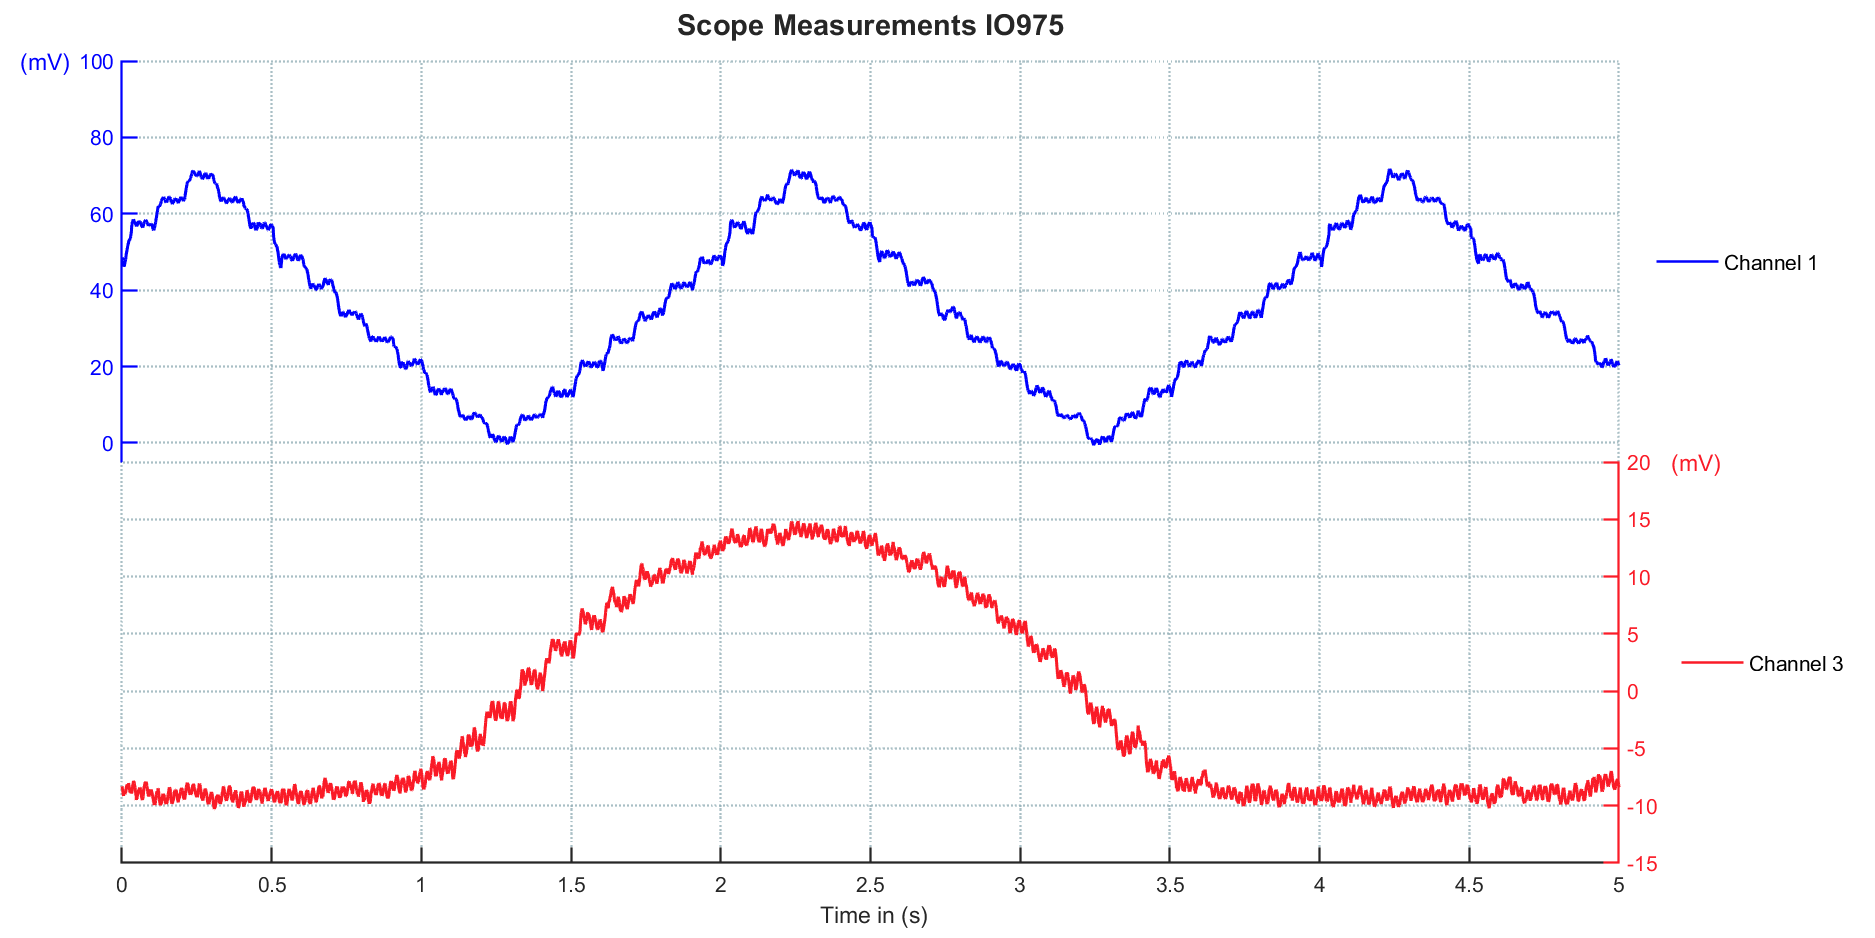

## Additional References

- [IO975 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io974_io975)

- [Approximating Nonlinear Relationships: Type S Thermocouple](https://www.mathworks.com/help/simulink/slref/approximating-nonlinear-relationships-type-s-thermocouple.html)